## Exo1


n=20;
X=zeros(3,n);
X(:,1)=[1,1,1]

X =      1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



for i=2:n
    X(:,i)=[0,X(2,i-1)/2,-(cos(X(3,i-1))+X(3,i-1)*sin(X(3,i-1)))/(2-sin(X(3,i-1)))];
end
X(:,n)

ans =          0
    0.0000
   -0.4502


X

X =     1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    1.0000    0.5000    0.2500    0.1250    0.0625    0.0312    0.0156    0.0078    0.0039    0.0020    0.0010    0.0005    0.0002    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000
    1.0000   -1.1927   -0.5044   -0.4507   -0.4502   -0.4502   -0.4502   -0.4502   -0.4502   -0.4502   -0.4502   -0.4502   -0.4502   -0.4502   -0.4502   -0.4502   -0.4502   -0.4502   -0.4502   -0.4502


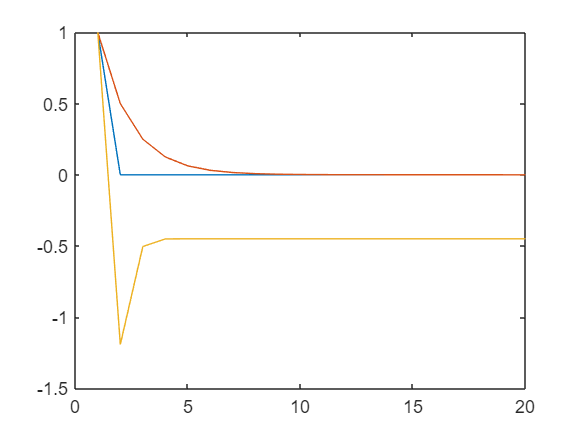

plot(X(1,:))
hold on
plot(X(2,:))
hold on
plot(X(3,:))


A=1+X(1,n)^2+abs(X(2,n)^3)+X(3,n)^2+sin(X(3,n))

A = 0.7675

## Exo 4

epsilon=1/10;
rho=epsilon/3;
N=100;
u0=randn(1,2*N);
U=[u0];
k=1;
[val,grad]=energie(u0);


while abs(energie(U(k))(1)+1/epsilon*penalisation(U(k)(1)))>1/1000

    U=[U;U(k)-epsilon*(energie(U(k)(2)+1/epsilon*penalisation(U(k)(2))))]
    k=k+1;
end

 Invalid array indexing.


for i=1:length(U)
    X=U(i)(1:N);
    Y=U(i)(N+1:2*N);
    plot(X,Y)
end

function [val,grad]=energie(u)
N=length(u)/2;
Y=u(N+1:2*N);
val=1/(1+N)*sum(Y);
grad=zeros(1,2*N);
for i=N+1:2*N
    grad(i)=1/(1+N)
end
end
